robot = importrobot("robot.urdf");
q = homeConfiguration(robot);
dof = length(q);

if exist("wcli", "var")
    clib.webcface.wcfClose(wcli);
end
addpath("./webcface")
configObj = clibConfiguration("webcface", ExecutionMode="outofprocess")

configObj =  プロパティをもつ webcface の CLibraryConfiguration:

    InterfaceLibraryPath: "C:\Users\mech-user\3a_pro\ik\webcface\webcfaceInterface.dll"
               Libraries: ["webcface.dll"    "spdlogd.dll"]
                  Loaded: 1
           ExecutionMode: outofprocess
               ProcessID: 16432


wcli = clib.webcface.wcfInit("matlab-test", "127.0.0.1", 7530);
clib.webcface.wcfStart(wcli);

初期状態にする (ボタンを押すと実行)

 
q = homeConfiguration(robot);
qs = ["0" "0" "0" "0" "0" "0" "0"];
reverse = [1 1 1 -1 1 -1 1];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(floor(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500));
end
clib.webcface.wcfFuncRunS(wcli, "bullet-sim", "move_servo", qs)

ans = ""

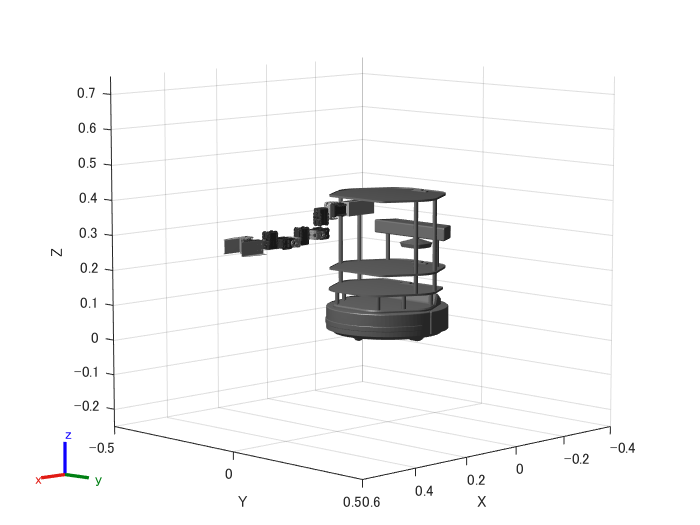

show(robot, q, Frames="off");
xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])

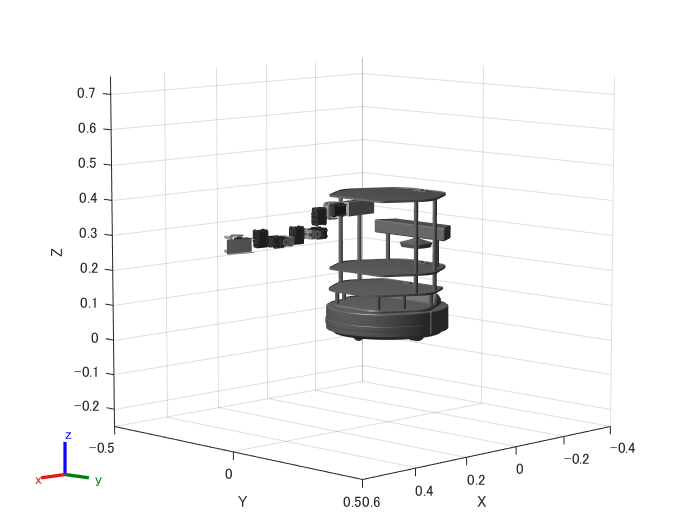

% q(1) -> y+
q(1).JointPosition = deg2rad(-10);
% q(2) -> 正面から見て反時計回り
q(2).JointPosition = deg2rad(0);
% q(3) -> z+
q(3).JointPosition = deg2rad(0);
% q(4) -> 正面から見て反時計回り  実機では逆？
q(4).JointPosition = deg2rad(0);
% q(5) -> z+
q(5).JointPosition = deg2rad(0);
% q(6) -> 正面から見て反時計回り  実機では逆？
q(6).JointPosition = deg2rad(0);
% q(7) -> +で開く -50くらいで閉じる
q(7).JointPosition = deg2rad(-60);
show(robot, q, Frames="off");
xlim([-0.4 0.6])
ylim([-0.5 0.5])
zlim([-0.25 0.75])


qs = ["0" "0" "0" "0" "0" "0" "0"];
reverse = [1 1 1 1 1 1 1];
for j = 1:7
    % radをdegにし、±150度を0～1023にする
    qs(j) = num2str(floor(rad2deg(q(j).JointPosition) * reverse(j) / 300 * 1023 + 500));
end
clib.webcface.wcfFuncRunS(wcli, "bullet-sim", "move_servo", qs)

ans = ""